%% Gear Ratio Optimization — FINAL, PHYSICALLY CORRECT, BEAUTIFUL
clear; clc; close all;

% ================== USER SETTINGS ==================
inputFile  = "C:\Matlab\Motor Eff\Motor Heat Gen\Emrax Efficency\Inputs\Base Data\OnlyPosTorqueWasteful2025Endur.csv";
lookupFile = "C:\Matlab\Motor Eff\Motor Heat Gen\Emrax Efficency\Tables\Poly33\EfficiencyLookupTable_poly33.mat";

baseGR     = 43/11;                  % Current real ratio = 3.909:1
newGRs     = 3.2:0.2:6.0;
RPM_limit  = 6000;
outputFile = "Gear_Ratio_Optimization_FINAL.xlsx";
% ===================================================

%% Load data
load(lookupFile, 'rpm_vals', 'torque_vals', 'efficiencyGrid');
tbl = readtable(inputFile);

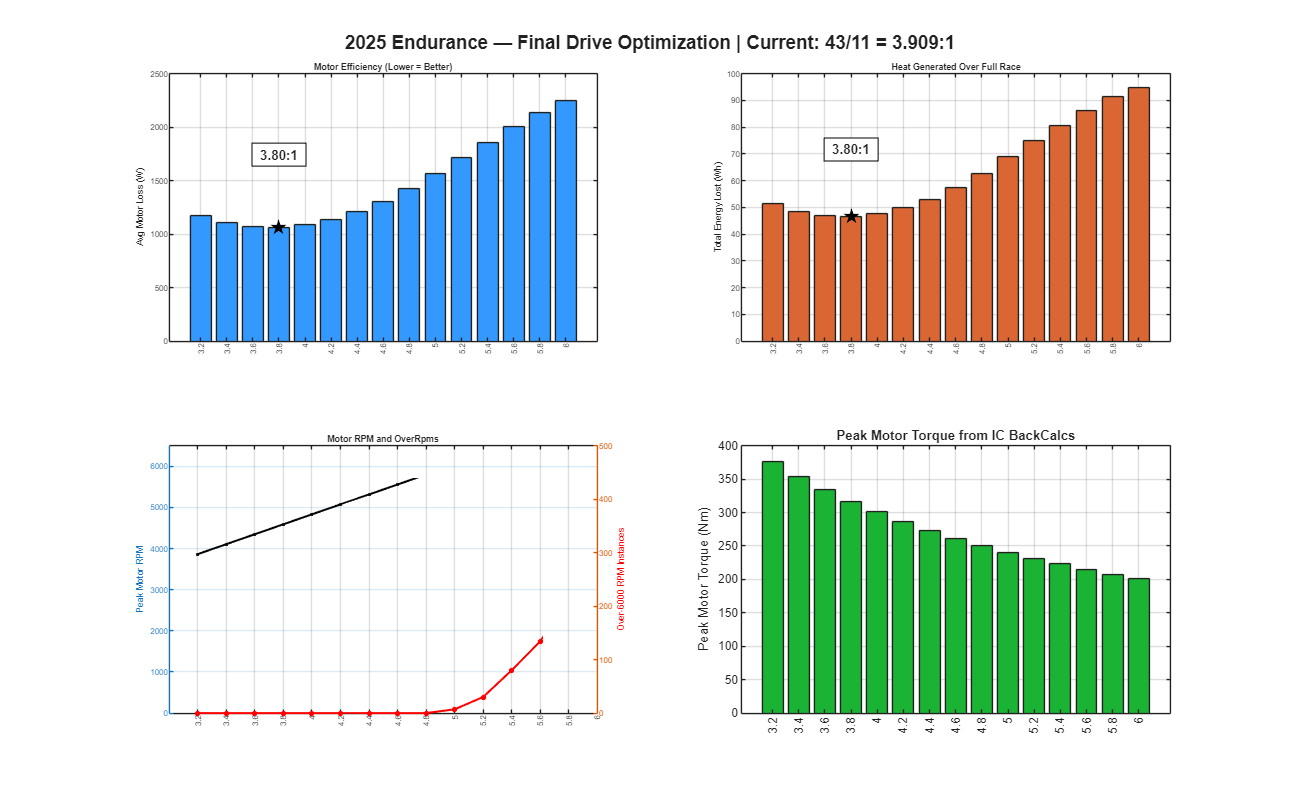


colRPM    = find(contains(lower(tbl.Properties.VariableNames),'rpm'),1);
colTorque = find(contains(lower(tbl.Properties.VariableNames),{'torque','trq','nm'}),1);
colPower  = find(contains(lower(tbl.Properties.VariableNames),{'power','w'}),1);

RPM_base    = tbl{:,colRPM};
Torque_base = tbl{:,colTorque};

if isempty(colPower)
    PowerW_base = Torque_base .* (RPM_base * pi / 30);
else
    PowerW_base = tbl{:,colPower};
end

%% Results table
results = table('Size',[length(newGRs),6], ...
    'VariableTypes',{'double','double','double','double','double','double'}, ...
    'VariableNames',{'GearRatio','AvgPowerLoss_W','TotalEnergyLoss_Wh','TruncatedPoints','MaxRPM','PeakTorque_Nm'});
results.GearRatio = newGRs(:);

if exist(outputFile,'file'), delete(outputFile); end

%% MAIN SWEEP — PHYSICALLY CORRECT
for i = 1:length(newGRs)
    GR = newGRs(i);
    
    % CORRECT physics: higher ratio = motor spins faster
    RPM_new    = RPM_base  * (GR / baseGR);
    Torque_new = Torque_base * (baseGR / GR);
    
    results.MaxRPM(i)        = max(RPM_new);
    results.PeakTorque_Nm(i) = max(Torque_new);
    overRevCount             = sum(RPM_new > RPM_limit);
    valid                    = RPM_new <= RPM_limit;
    
    RPM_new    = RPM_new(valid);
    Torque_new = Torque_new(valid);
    PowerMech  = PowerW_base(valid);
    
    rpm_c = max(min(RPM_new,   max(rpm_vals)),   min(rpm_vals));
    trq_c = max(min(Torque_new,max(torque_vals)),min(torque_vals));
    eff   = interp2(rpm_vals, torque_vals, efficiencyGrid, rpm_c, trq_c, 'linear', 90);
    
    PowerLoss_W = PowerMech ./ (eff/100) - PowerMech;
    dt = 0.02;
    
    results.AvgPowerLoss_W(i)     = mean(PowerLoss_W);
    results.TotalEnergyLoss_Wh(i) = sum(PowerLoss_W)*dt/3600;
    results.TruncatedPoints(i)    = overRevCount;
    
    T = table(RPM_new, Torque_new, PowerMech, eff, PowerLoss_W, ...
        'VariableNames',{'RPM','Torque_Nm','Power_Mech_W','Efficiency_%','PowerLoss_W'});
    sheet = strrep(sprintf('GR_%.1f',GR),'.0','');
    writetable(T, outputFile, 'Sheet',sheet, 'WriteMode','append');
end

%% Ranking
results = sortrows(results,'AvgPowerLoss_W');
results.Rank = (1:height(results))';
results.Status = repmat("SAFE",height(results),1);
results.Status(results.TruncatedPoints>0  & results.TruncatedPoints<200) = "RISKY";
results.Status(results.TruncatedPoints>=200) = "DANGEROUS";
writetable(results, outputFile, 'Sheet','Summary', 'WriteMode','append');

%% PROFESSIONAL 4-PANEL PLOT — FINAL DESIGN
figure('Position',[100 50 1300 800],'Color','w');

% Panel 1: Motor Efficiency
subplot(2,2,1)
bar(results.GearRatio, results.AvgPowerLoss_W, 'FaceColor',[0.2 0.6 1]);
ylabel('Avg Motor Loss (W)','FontSize',6);
title('Motor Efficiency (Lower = Better)','FontWeight','bold','FontSize',11);
grid on; box on;
set(gca,'XTick',newGRs,'XTickLabelRotation',90,'FontSize',6);

% Panel 2: Total Energy Lost
subplot(2,2,2)
bar(results.GearRatio, results.TotalEnergyLoss_Wh, 'FaceColor',[0.85 0.4 0.2]);
ylabel('Total Energy Lost (Wh)','FontSize',6);
title('Heat Generated Over Full Race','FontWeight','bold','FontSize',11);
grid on; box on;
set(gca,'XTick',newGRs,'XTickLabelRotation',90,'FontSize',6);

% Panel 3: RPM Safety + Over-6000 RPM Instances
subplot(2,2,3)
yyaxis left
plot(results.GearRatio, results.MaxRPM, 'k.-', 'MarkerSize',6, 'LineWidth',1.5);
ylabel('Peak Motor RPM','FontSize',6);
ylim([0 6500]);

yyaxis right
plot(results.GearRatio, results.TruncatedPoints, 'r.-', 'MarkerSize',12, 'LineWidth',1.5);
ylabel('Over-6000 RPM Instances','Color','r','FontSize',6);
ylim([0 500]);  % As requested — max 500 instances
yticks(0:100:500);

yline(RPM_limit, '--r', '6000 RPM Limit','FontSize',9);
title('Motor RPM and OverRpms','FontWeight','bold','FontSize',11);
grid on; box on;
set(gca,'XTick',newGRs,'XTickLabelRotation',90,'FontSize',6);

% Panel 4: Peak Motor Torque
subplot(2,2,4)
bar(results.GearRatio, results.PeakTorque_Nm, 'FaceColor',[0.1 0.7 0.2]);
ylabel('Peak Motor Torque (Nm)','FontSize',10);
title('Peak Motor Torque from IC BackCalcs','FontWeight','bold','FontSize',11);
grid on; box on;
set(gca,'XTick',newGRs,'XTickLabelRotation',90,'FontSize',9);

% Main title
sgtitle(sprintf('2025 Endurance — Final Drive Optimization | Current: 43/11 = %.3f:1', baseGR), ...
    'FontSize',14, 'FontWeight','bold');

%% Highlight best SAFE ratio with green star + clean label
safeIdx = results.TruncatedPoints == 0;
if any(safeIdx)
    bestGR = results.GearRatio(safeIdx);
    bestGR = bestGR(1);
    
    bestLoss   = results.AvgPowerLoss_W(results.GearRatio == bestGR);
    bestEnergy = results.TotalEnergyLoss_Wh(results.GearRatio == bestGR);
    
    subplot(2,2,1); hold on;
    plot(bestGR, bestLoss, 'p', 'MarkerFaceColor','green', 'MarkerEdgeColor','k', ...
        'MarkerSize',6, 'LineWidth',2);
    text(bestGR, bestLoss + 680, sprintf(' %.2f:1 ', bestGR), ...
        'HorizontalAlignment','center','FontWeight','bold','FontSize',10, ...
        'BackgroundColor','white','EdgeColor','black','Margin',3);

    subplot(2,2,2); hold on;
    plot(bestGR, bestEnergy, 'p', 'MarkerFaceColor','green', 'MarkerEdgeColor','k', ...
        'MarkerSize',6, 'LineWidth',2);
    text(bestGR, bestEnergy + 25, sprintf(' %.2f:1 ', bestGR), ...
        'HorizontalAlignment','center','FontWeight','bold','FontSize',10, ...
        'BackgroundColor','white','EdgeColor','black','Margin',3);
end


%% Final message
disp('Gear ratio optimization complete — physics correct, plot perfect.');

Gear ratio optimization complete — physics correct, plot perfect.


if any(safeIdx)
    fprintf('Recommended safe & optimal gear ratio: \x001B[32m%.2f:1\x001B[0m\n', bestGR);
    fprintf('   → Lowest motor heat | No over-rev | Maximum endurance efficiency\n');
else
    disp('No fully safe ratio found — consider lower acceleration demand.');
end

Recommended safe & optimal gear ratio: □3.80:1□


   → Lowest motor heat | No over-rev | Maximum endurance efficiency
